# Brain Scan Demo

*Koby Taswell and Ayush Garg*

This demo tests Optimal Hard Thresholding applied to each slice along Z axis.

filename = 'ABIDE_MRI_data.nii';

Vol = niftiread(filename);

[Nvol, Dvol, snrN, snrD] = TestVolume(Vol);
[NvolSq, DvolSq, snrNSq, snrDSq] = TestVolumeSq(Vol);


**For Arbitrary thresholding**

Original Signal to Noise Ratio at each Slice along Z axis

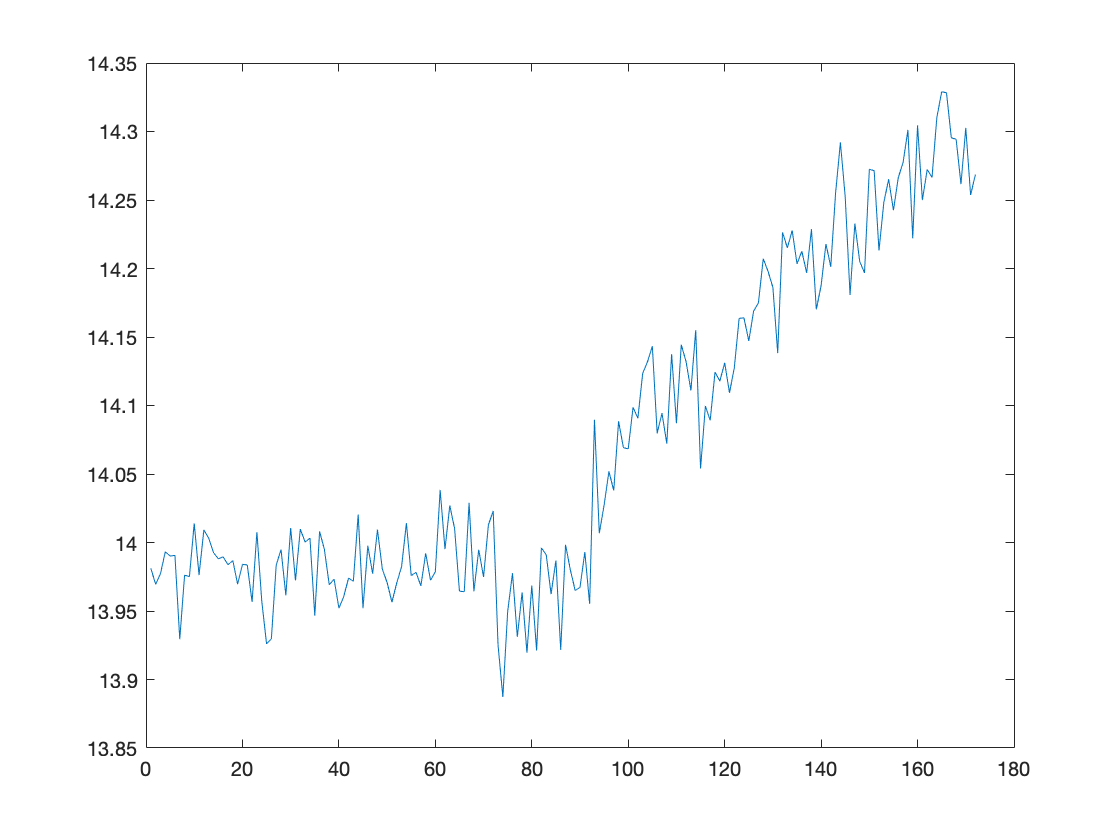

plot(snrN)

Denoised Signal to Noise Ratio at each slice along Z axis

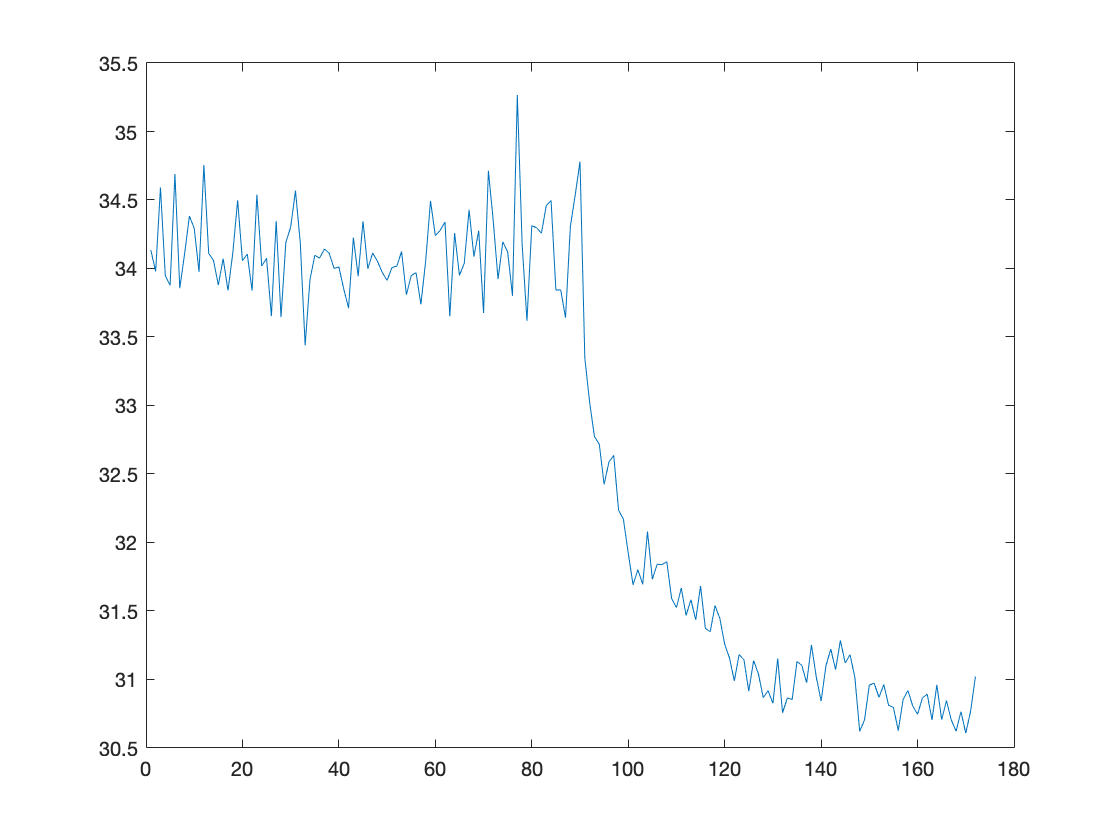

plot(snrD)

Amount of Signal to Noise Reduced by Arbitrary Optimal Hard Thresholding

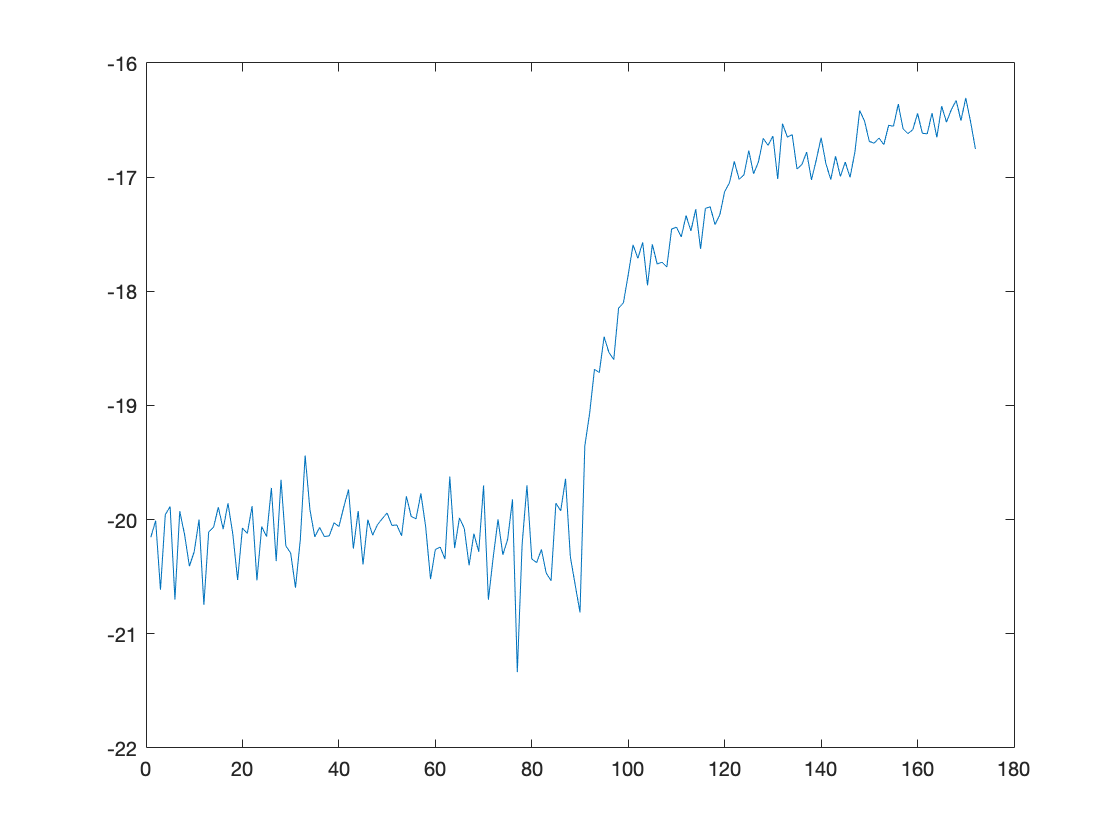

plot(snrN - snrD)

**For non-arbitrary square thresholding**

Original Signal to Noise Ration at each slice along Z axis 

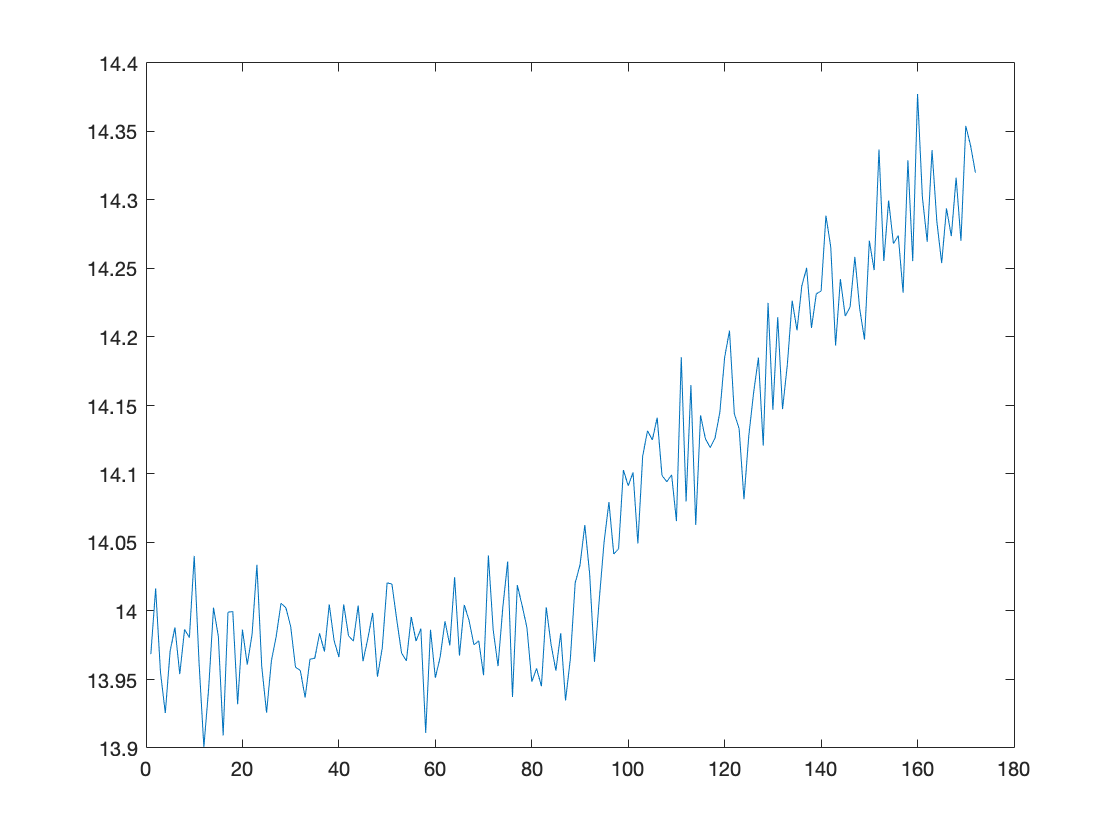

plot(snrNSq)

Denoised Signal to Noise Ratio at each slice along Z axis

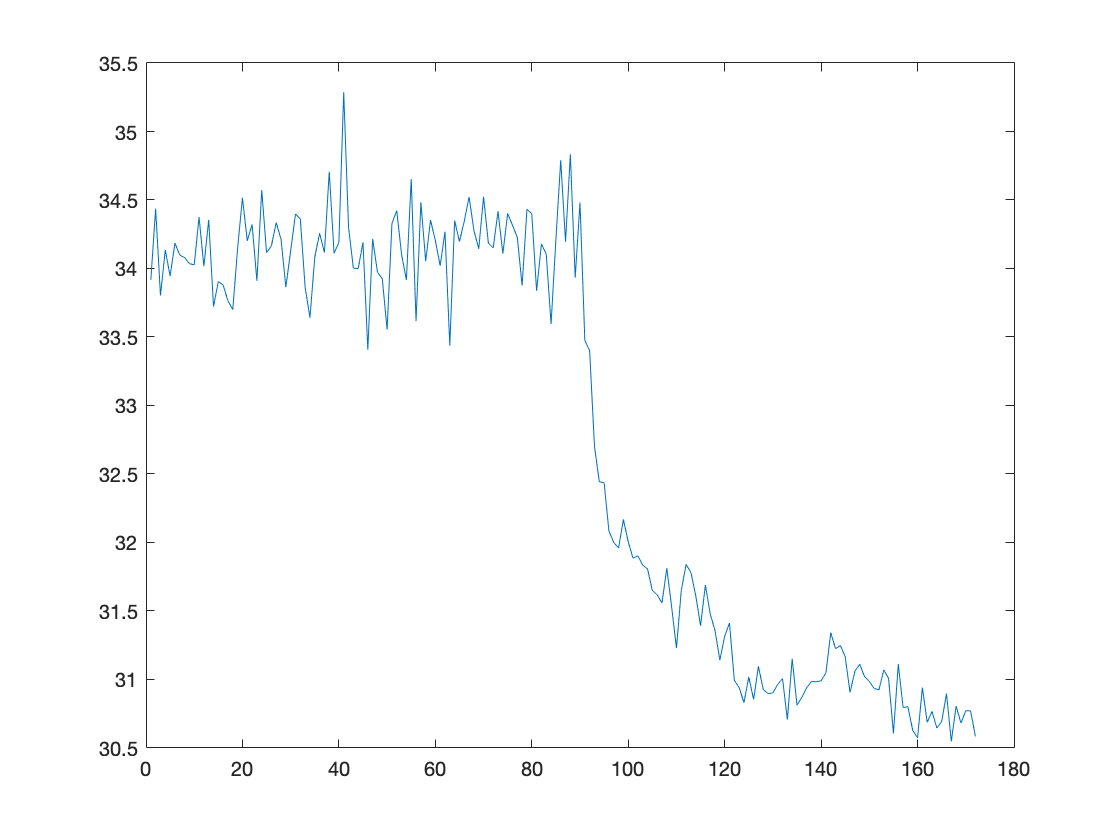

plot(snrDSq)

Amount of Signal to Noise Reduced by Arbitrary Optimal Hard Thresholding

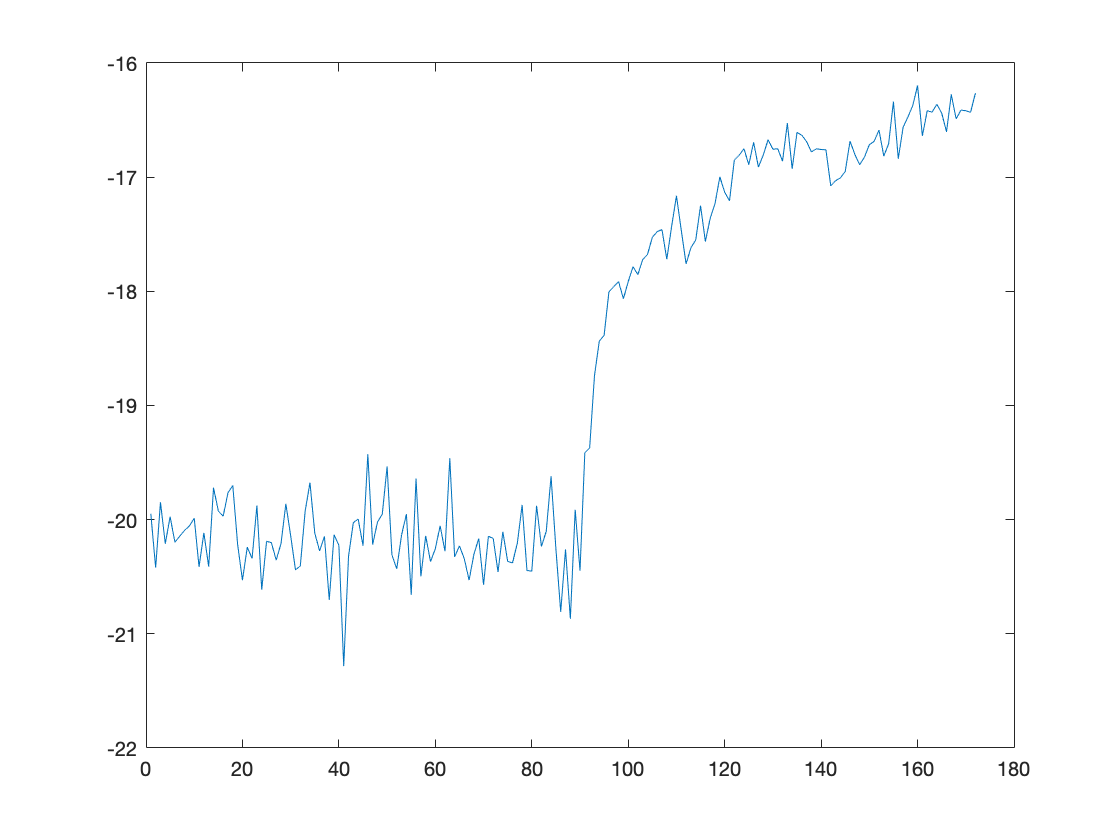

plot(snrNSq - snrDSq)

**Example Brain Scan (Original, Noisey, Denoised)**

Arbitrary Thresholding

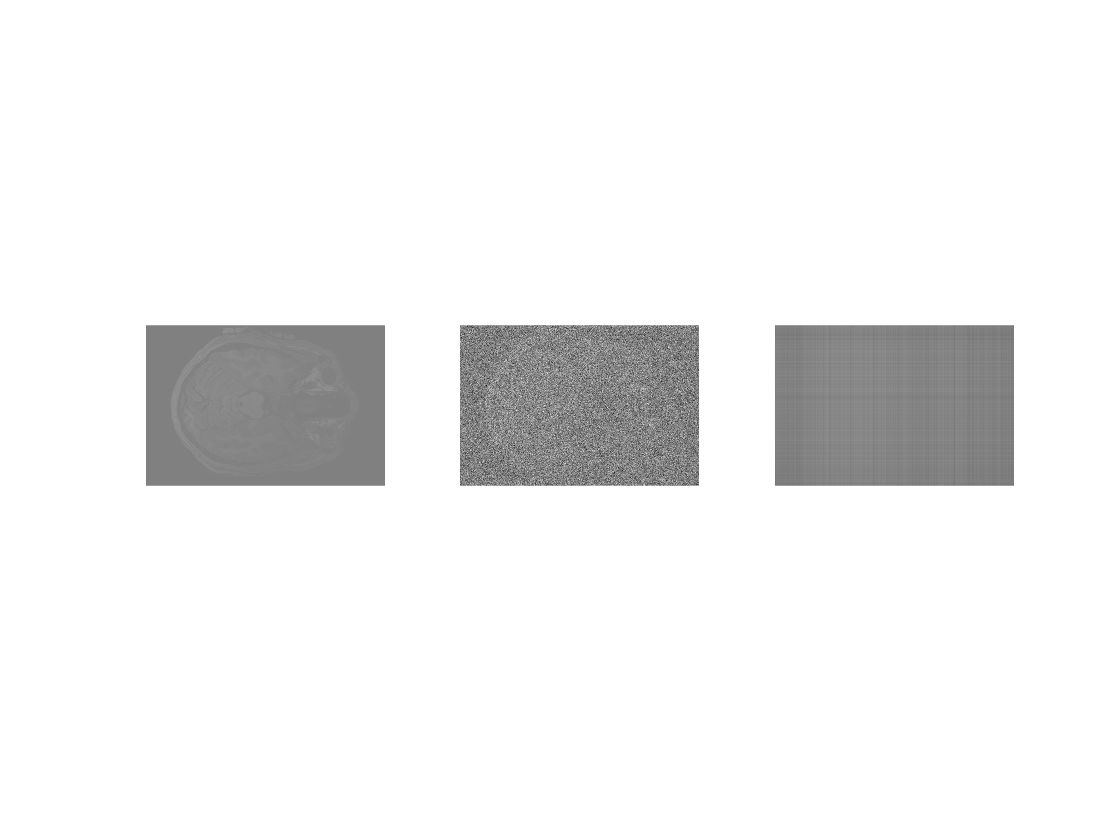

subplot(1,3,1)
imshow(Vol(:, :, 140));

subplot(1,3,2)
imshow(Nvol(:, :, 140));

subplot(1,3,3)
imshow(Dvol(:, :, 140))

Non-arbitrary thresholding

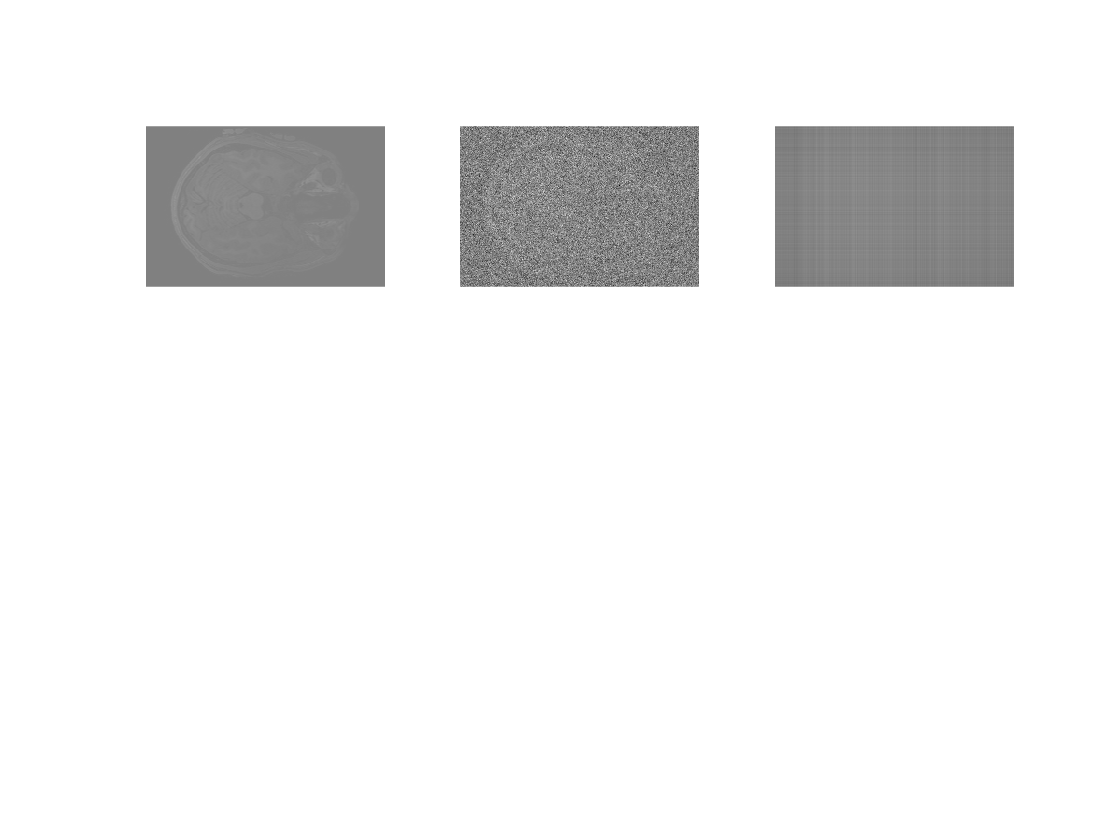

clf
subplot(2,3,1)
imshow(Vol(:, :, 140));

subplot(2,3,2)
imshow(NvolSq(:, :, 140));

subplot(2,3,3)
imshow(DvolSq(:, :, 140))